# Simulate HIV Infection

viewSolution(false)

The human immunodeficiency virus (HIV) infection spreads and can develop into acquired immunodeficiency syndrome (AIDS). AIDS can lead to immune system failure and eventual inability to defend the body against infection or cancer. Without treatment with antiretroviral drugs, survival time after infection with HIV is about 9 to 11 years, depending on a number of factors. Antiretroviral drugs such as TDF (tenofovir), either 3TC (lamivudine) or FTC (emtricitabine), and EFV (efavirenz) are recommended by the World Health Organization as soon as HIV infection is diagnosed. This simulation predicts the spread of HIV infection in a body with an initial infection.

The spread of HIV in a patient is approximated with balance equations on (**H**)ealthy, (**I**)nfected, and (**V**)irus population counts.

Your assignment is to model the healthy, infected, and virus count over 15 years subject to the parameters and equations below. The simulation should be similar to the sketch below which includes patient data.

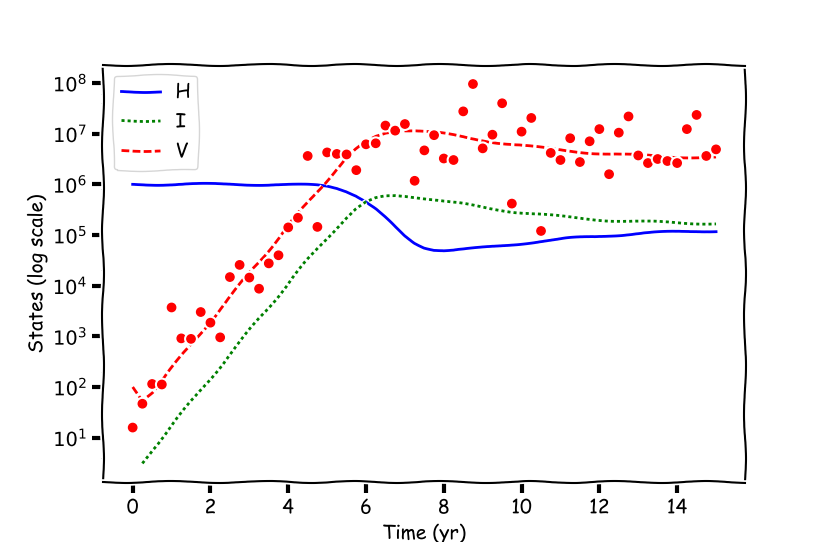

After simulating with ODE45, create a semi-log-y plot that shows the progress of the infection. The final report should include:

- A semi-log-y plot that shows the progress of infection such as the sketch above.

- Discuss what terms you would adjust to match HIV lab data that measures the virus in a patient.

- Suppose that a new antiretroviral drug is evaluated in clinical trials. Virus count data is collected over many years to control the HIV infection. Discuss what terms could be added to the differential equations to simulate the effect of an antiretroviral drug.

## Assignment Summary

- Add Initial Values to z0 Array in the cell below Equations

- Add Equations to the simulate_infection function

- Graph the results of ODE45 in a semi-log-y plot

- Write a brief report

### Goal: Simulate an HIV Infection

#### Initial Values

clc; clear all; close all
H0 = 1e6  % Healthy Cells

H0 = 1000000

I0 = 0  % Infected Cells

I0 = 0

V0 = 100  % Virus

V0 = 100

#### Parameters

kr1 = 1e5  % New healthy cells per year

kr1 = 100000

kr2 = 0.1  % Death rate of healthy cells

kr2 = 0.1000

kr3 = 2e-7  % Healthy cells converting to infected cells

kr3 = 2.0000e-07

kr4 = 0.5  % Death rate of infected cells

kr4 = 0.5000

kr5 = 5  % Death rate of virus

kr5 = 5

kr6 = 100  % production of virus by infected cells

kr6 = 100

#### Equations

The following equations are transient balances on the number of healthy cells (**H**), infected cells (**I**), and the virus count (**V**).


$$\frac{dH(t)}{dt} = kr_1 - kr_2H(t) - kr_3H(t)V(t)$$



$$\frac{dI(t)}{dt} = kr_3H(t)V(t)-kr_4I(t)
$$



$$\frac{dV(t)}{dt} = -kr_3H(t)V(t) -kr_5V(t) +kr_6I(t)$$


times = linspace(0, 15, 1501);
% cells = [Healthy; Infected; Virus] for each time point

INPUT INITIAL VALUES IN z0 ARRAY BELOW IN ORDER OF HEALTHY< INFECTED, VIRUS

z0 = []

### Simulate

EDIT THE `simulate_infection` FUNCTION BELOW

THEN, SIMULATE OVER THE `times` WITH `ode45`

### Plot

CREATE SEMI-LOG-Y PLOT HERE 

### Function

function dzdt = simulate_infection(t, z)
% Values at a given moment
H = z(1);
I = z(2);
V = z(3);


clc; clear all; close all
times = linspace(0, 15, 1501);
% cells = [Healthy; Infected; Virus] for each time point
% INPUT INITIAL VALUES IN z0 ARRAY BELOW
%%%%%%%%%%%%%%%%%%%%
z0 = [1e6; 0; 100;]; % initialize initial values

[t, z] = ode45(@(t, z) simulate_infection(t, z), times, z0);

% INPUT SEMI-LOG-Y PLOT HERE
%%%%%%%%%%%%%%%%%%%%
title('Simulated Virus')
h = semilogy(t, z(:, 1));
hold on;
i = semilogy(t, z(:, 2));
hold on;
v = semilogy(t, z(:, 3));
xlabel('Time (years')
ylabel('Cell Counts (log count)')
legend({'Healthy', 'Infected', 'Virus'})

function dzdt = simulate_infection(t, z)
% Values at a given moment
H = z(1);
I = z(2);
V = z(3);

% parameters
kr1 = 1e5; % new healthy cells per year
kr2 = 0.1; % death rate of healthy cells
kr3 = 2e-7; % healthy cells converting to infected cells
kr4 = 0.5; % death rate of infected cells
kr5 = 5; % death rate of virus
kr6 = 100; % production of virus by infected cells

% INSERT EQUATIONS HERE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% parameters
kr1 = 1e5; % new healthy cells per year
kr2 = 0.1; % death rate of healthy cells
kr3 = 2e-7; % healthy cells converting to infected cells
kr4 = 0.5; % death rate of infected cells
kr5 = 5; % death rate of virus
kr6 = 100; % production of virus by infected cells


INSERT EQUATIONS HERE

dHdt = 0;
dIdt = 0;
dVdt = 0;

LEAVE CODE BELOW


% return column vector
dzdt = [dHdt; dIdt; dVdt];
end

### Solution:

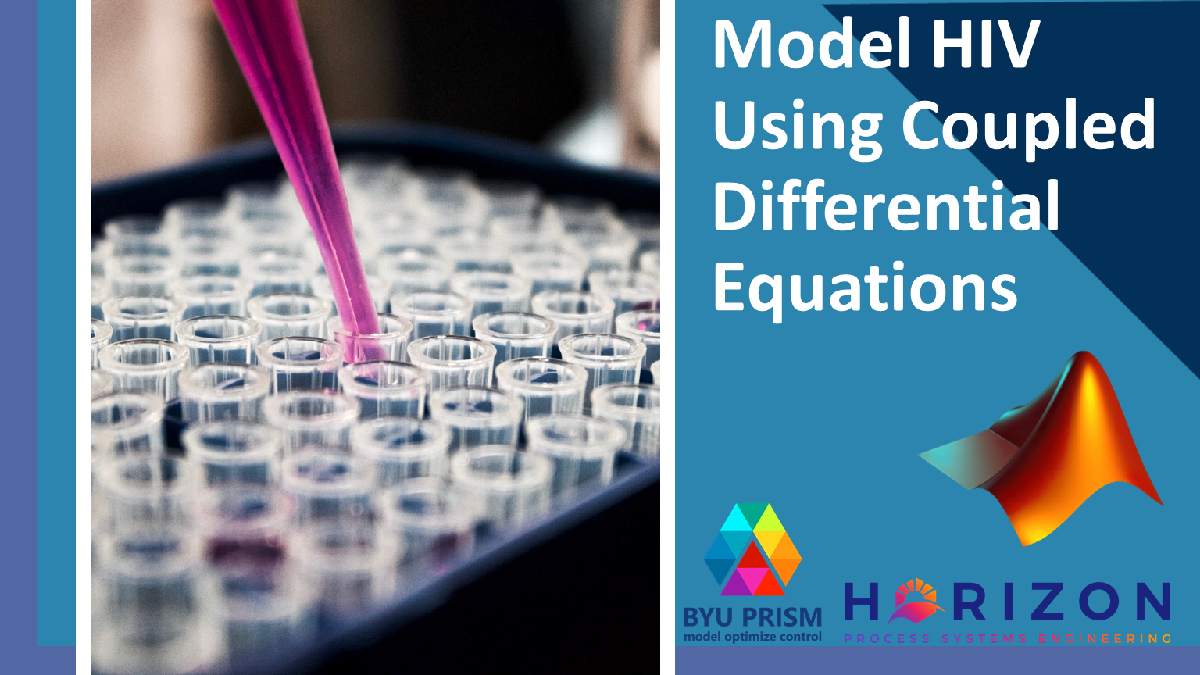

[View Solution Video](https://youtu.be/A4rBltOLhhQ)

function viewSolution(view)
if view
    disp("clc; clear all; close all" + newline + ...
         "times = linspace(0, 15, 1501);" + newline + ...
         "% cells = [Healthy; Infected; Virus] for each time point" + newline + ...
         "% INPUT INITIAL VALUES IN z0 ARRAY BELOW" + newline + ...
         "%%%%%%%%%%%%%%%%%%%%" + newline + ...
         "z0 = [1e6; 0; 100;]; % initialize initial values" + newline + ...
         "" + newline + ...
         "[t, z] = ode45(@(t, z) simulate_infection(t, z), times, z0);" + newline + ...
         "" + newline + ...
         "% INPUT SEMI-LOG-Y PLOT HERE" + newline + ...
         "%%%%%%%%%%%%%%%%%%%%" + newline + ...
         "title('Simulated Virus')" + newline + ...
         "h = semilogy(t, z(:, 1));" + newline + ...
         "hold on;" + newline + ...
         "i = semilogy(t, z(:, 2));" + newline + ...
         "hold on;" + newline + ...
         "v = semilogy(t, z(:, 3));" + newline + ...
         "xlabel('Time (years')" + newline + ...
         "ylabel('Cell Counts (log count)')" + newline + ...
         "legend({'Healthy', 'Infected', 'Virus'})" + newline + ...
         "" + newline + ...
         "function dzdt = simulate_infection(t, z)" + newline + ...
         "% Values at a given moment" + newline + ...
         "H = z(1);" + newline + ...
         "I = z(2);" + newline + ...
         "V = z(3);" + newline + ...
         "" + newline + ...
         "% parameters" + newline + ...
         "kr1 = 1e5; % new healthy cells per year" + newline + ...
         "kr2 = 0.1; % death rate of healthy cells" + newline + ...
         "kr3 = 2e-7; % healthy cells converting to infected cells" + newline + ...
         "kr4 = 0.5; % death rate of infected cells" + newline + ...
         "kr5 = 5; % death rate of virus" + newline + ...
         "kr6 = 100; % production of virus by infected cells" + newline + ...
         "" + newline + ...
         "% INSERT EQUATIONS HERE" + newline + ...
         "%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%" + newline + ...
         "% Equations" + newline + ...
         "dHdt = kr1 - kr2 * H - kr3 * H * V;" + newline + ...
         "dIdt = kr3 * H * V - kr4 * I;" + newline + ...
         "dVdt = - kr3 * H * V - kr5 * V + kr6 * I;" + newline + ...
         "%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%" + newline + ...
         "% LEAVE CODE BELOW" + newline + ...
         "" + newline + ...
         "% return column vector" + newline + ...
         "dzdt = [dHdt; dIdt; dVdt];" + newline + ...
         "end" + newline + ...
    	 "end")
end
end
